# Driving Pattern Basic Component

Copyright 2021 The MathWorks, Inc.

## Open the Model

mdl = "DrivingPatternBasic_test_harness";
if not(bdIsLoaded(mdl))
  open_system(mdl)
else
  DrivingPatternBasic_setup
end

## Load Inputs to Workspace

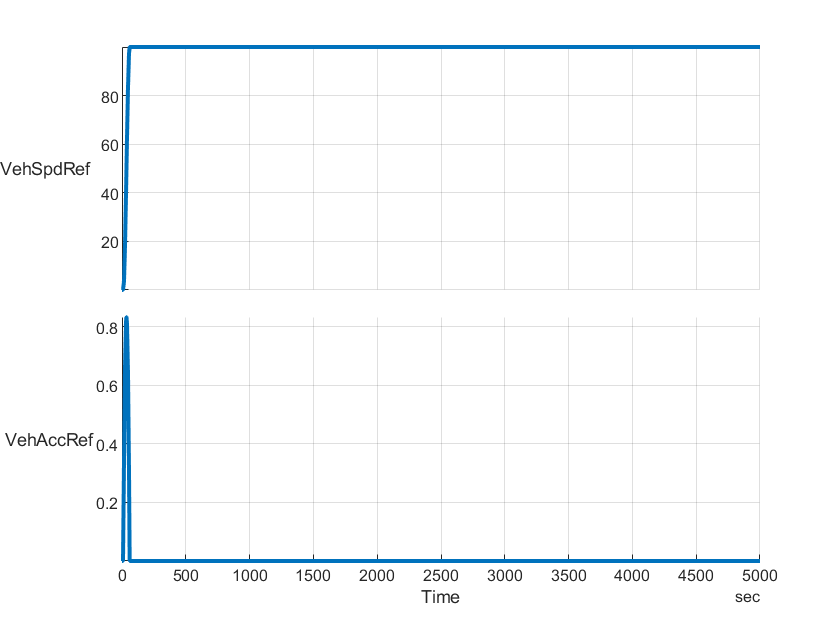

fig = figure;
[inputSignals_DrivingPattern, inputBus_DrivingPattern, initial, opt] = ...
  DrivingPatternBasic_inputs( "PlotParent",fig,...
    "PlotSpeedOnly",false, ...
    "InputPattern","high_speed", ...
    "TimeStep",0.1 );

summary(inputSignals_DrivingPattern.VehAccRef)

RowTimes:

    Time: 50001×1 duration
        Values:
            Min           0 sec    
            Median        2500 sec 
            Max           5000 sec 
            TimeStep      0.1 sec  

Variables:

    VehAccRef: 50001×1 double

        Properties:
            Units:  m/s^2
            Continuity:  continuous
        Values:

            Min       -7.8949e-14
            Median              0
            Max           0.83333



t_end = opt.t_end

t_end = 5000

% FYI: Initial SOC is defined but not used in the driving pattern component.
initial

initial = struct with fields:
    HVBattery_SOC_pct: 95


drivingPattern.useFromWorkspace_tf = opt.useFromWorkspace

drivingPattern = struct with fields:
    useFromWorkspace_tf: 1


## Run Simulation

% Set simulation input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

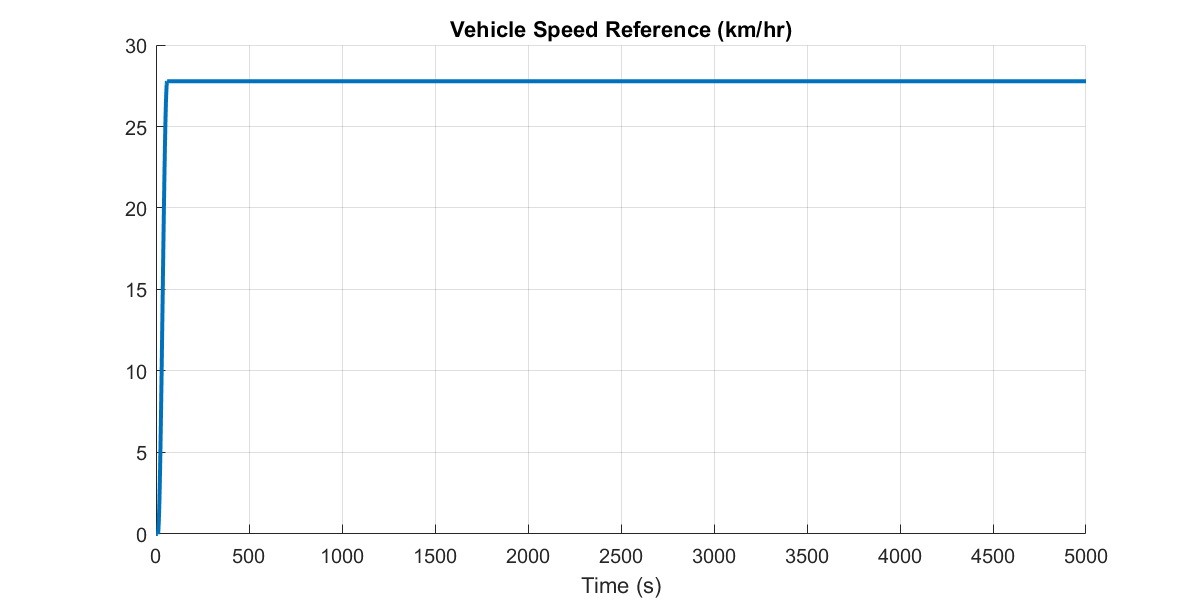

fig = figure;  hold on;  grid on
vals = out.logsout.get("<VehSpdRef>").Values;
plot(vals.Time, vals.Data, 'LineWidth',2)
xlabel("Time (s)")
title("Vehicle Speed Reference (km/hr)")
fig.Position(3:4) = [800 400];